# EE 451 Slideset 18

# MATLAB code pulled from slideset


M = 60; alpha = (M-1)/2; l = 0:M-1; wl = (2*pi/M)*l; 
Hrs = [ones(1,7),0.5925,0.1099,zeros(1,43),0.1099,0.5925,ones(1,6)]; 
Hdr = [1,1,0,0]; wdl = [0,0.2,0.3,1]; 
k1 = 0:floor((M-1)/2); k2 = floor((M-1)/2)+1:M-1; 
angH = [-alpha*(2*pi)/M*k1, alpha*(2*pi)/M*(M-k2)]; 
H = Hrs.*exp(j*angH); h = real(ifft(H,M)); 
%[db,mag,pha,grd,w] = freqz_m(h,1); [Hr,ww,a,L] = Hr_Type3(h);

% Slide 18, Example 
n = 0:1:length(h)-1;
Fs = 1000;
[db,mag,pha,grd,w] = freqz_m(h,[1]); 
delta_w = 2*pi/1000; 
wp = 500*2*pi/Fs;
ws = 600*2*pi/Fs;
Rp = -(min(db(1:1:ceil(wp/delta_w+1)))) % Actual Passband Ripple 

Rp = Inf

As = -round(max(db(floor(ws/delta_w+1):1:501))) % Min Stopband Attenuation 


As =

  1×0 empty double row vector



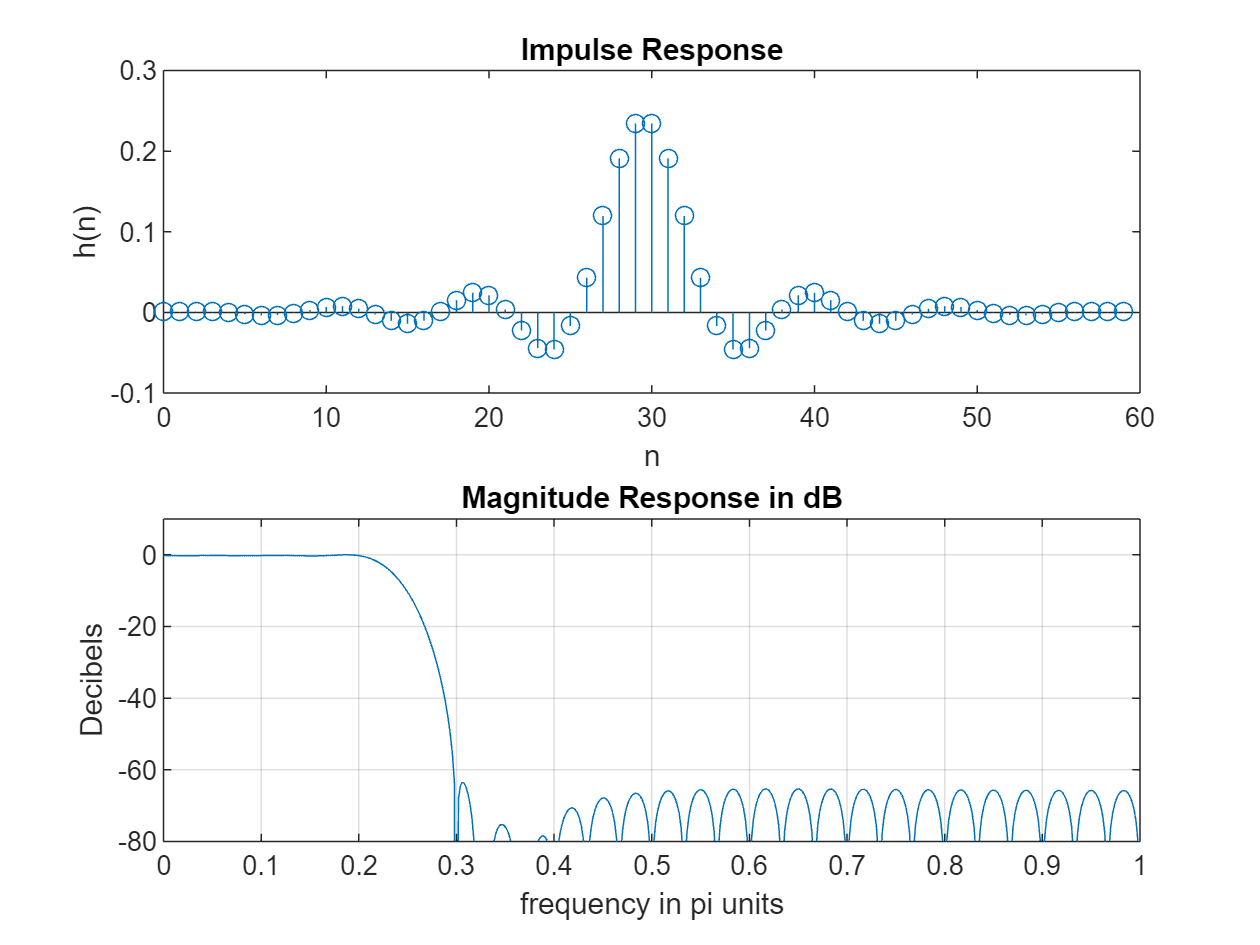

% Plots
figure;
subplot(2,1,1); stem(n,h);title('Impulse Response') 
xlabel('n'); ylabel('h(n)') 
subplot(2,1,2);plot(w/pi,db);title('Magnitude Response in dB');
grid; 
axis([0 1 -80 10]); 
xlabel('frequency in pi units'); ylabel('Decibels') 


% Slide 18, Example 1
clear;
Rp=3; %passband ripple;
As=40; %stopband attenuation
Fs=2000; %sampling fequency
f=[500 600]; %cutoff frequency
a=[1 0]; %desired amplitudes
% deviations, changing from dB
d1 = (1-db2mag(-Rp))/(1+db2mag(-Rp))

d1 = 0.1710

d2 = db2mag(-As)*(1+d1)

d2 = 0.0117

d=[ d1 d2 ];


[M, fo, ao, W]=firpmord(f,a,d,Fs);
h = firpm(M,fo, ao, W)

h =     0.0015    0.0445    0.0666    0.0087   -0.0490    0.0069    0.0658   -0.0329   -0.1102    0.1215    0.4749    0.4749    0.1215   -0.1102   -0.0329    0.0658    0.0069   -0.0490    0.0087    0.0666    0.0445    0.0015


n = 0:1:length(h)-1;
[db,mag,pha,grd,w] = freqz_m(h,[1]); 
delta_w = 2*pi/1000; 
wp = 500*2*pi/Fs;
ws = 600*2*pi/Fs;
Rp = -(min(db(1:1:ceil(wp/delta_w+1)))) % Actual Passband Ripple 

Rp = 3.4712

As = -round(max(db(floor(ws/delta_w+1):1:501))) % Min Stopband Attenuation 

As = 39

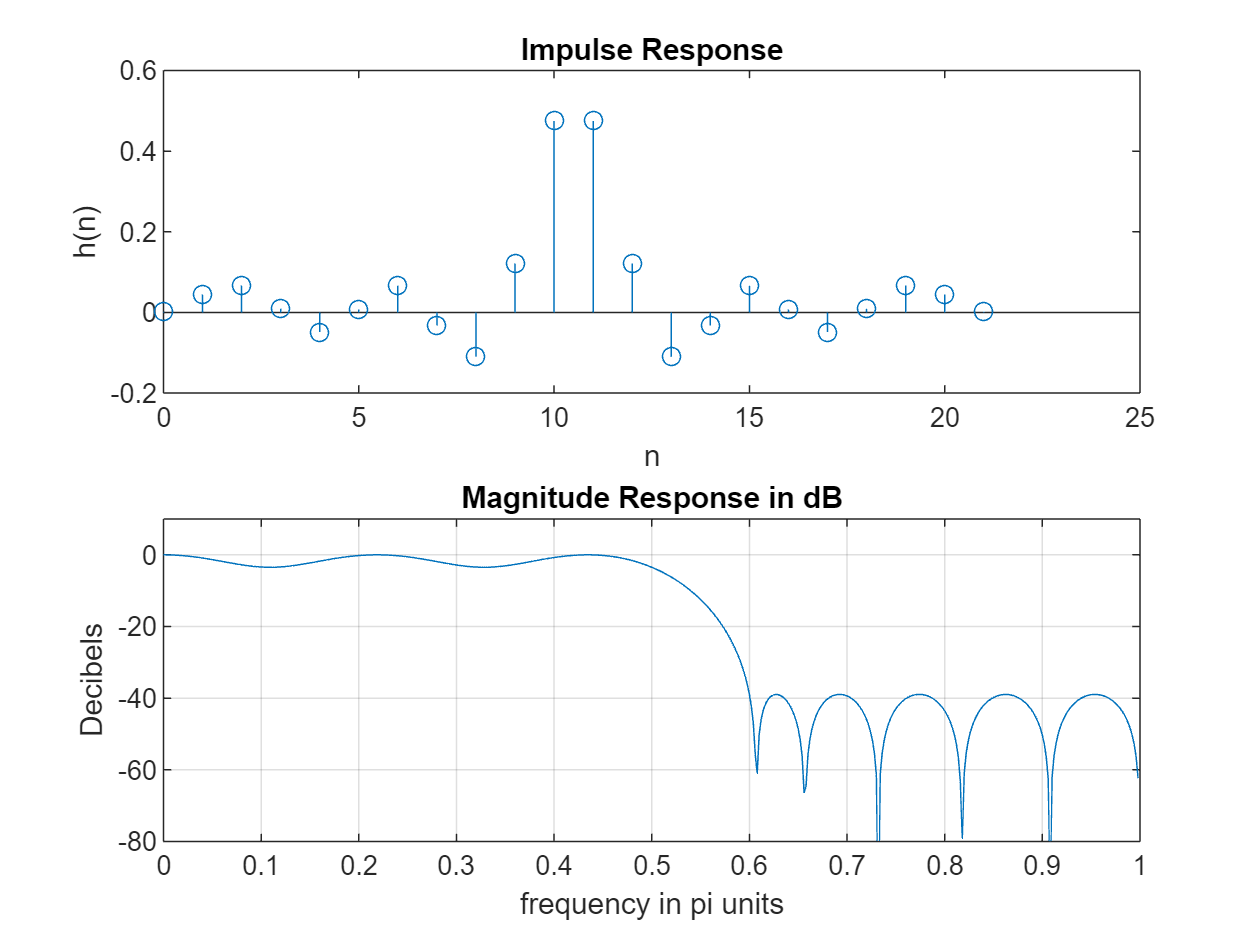

% Plots
figure;
subplot(2,1,1); stem(n,h);title('Impulse Response') 
%axis([0 N -0.1 0.3]);
xlabel('n'); ylabel('h(n)') 
subplot(2,1,2);plot(w/pi,db);title('Magnitude Response in dB');
grid; 
axis([0 1 -80 10]); 
xlabel('frequency in pi units'); ylabel('Decibels') 


% Slide 18, Example 1
clear;
Rp=3; %passband ripple;
As=40; %stopband attenuation
Fs=2000; %sampling fequency
f=[500 600]; %cutoff frequency
a=[1 0]; %desired amplitudes
% deviations, changing from dB
d1 = (1-db2mag(-Rp))/(1+db2mag(-Rp))

d1 = 0.1710

d2 = db2mag(-As)*(1+d1)

d2 = 0.0117

d=[ d1 d2 ];

% Slide 18, Example 2�
M = 45; As = 60; n=[0:1:M-1];
beta = 0.1102*(As-8.7)

beta = 5.6533

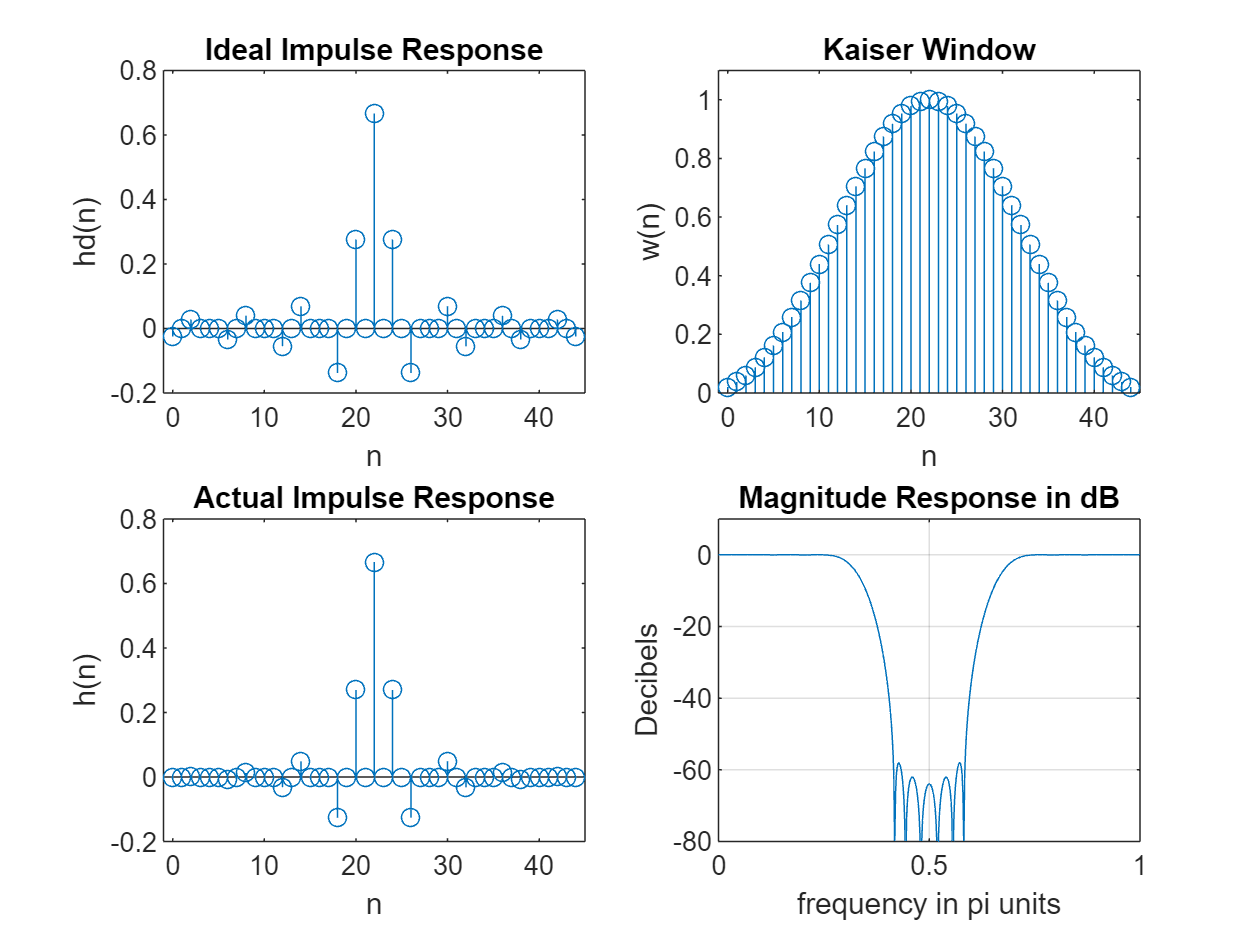

w_kai = (kaiser(M,beta))'; wc1 = pi/3; wc2 = 2*pi/3;
hd = ideal_lp(wc1,M) + ideal_lp(pi,M) - ideal_lp(wc2,M);
h = hd .* w_kai;
[db,mag,pha,grd,w] = freqz_m(h,[1]);
% Plots
figure;
subplot(2,2,1); stem(n,hd);
title('Ideal Impulse Response')
axis([-1 M -0.2 0.8]); xlabel('n'); ylabel('hd(n)')
subplot(2,2,2); stem(n,w_kai);title('Kaiser Window')
axis([-1 M 0 1.1]); xlabel('n'); ylabel('w(n)')
subplot(2,2,3); stem(n,h);title('Actual Impulse Response')
axis([-1 M -0.2 0.8]); xlabel('n'); ylabel('h(n)')
subplot(2,2,4);plot(w/pi,db); axis([0 1 -80 10]);
title('Magnitude Response in dB');grid;
xlabel('frequency in pi units'); ylabel('Decibels');

delta_w = 2*pi/1000;
% A proper solution should find the first time
% the signal drops below 60, and the the last
% time the signal was below 60, and compute
% max during that interval. We do by inspection
wcl = 0.422*pi;
wcu = 0.575*pi;
As = -round(max(db(floor(wcl/delta_w+1):1:ceil(wcu/delta_w+1))))

As = 58

% Attenuation is less than 60

% we increase beta
M = 45; As = 60; n=[0:1:M-1];
beta = 0.1102*(As-8.7) + 0.3

beta = 5.9533

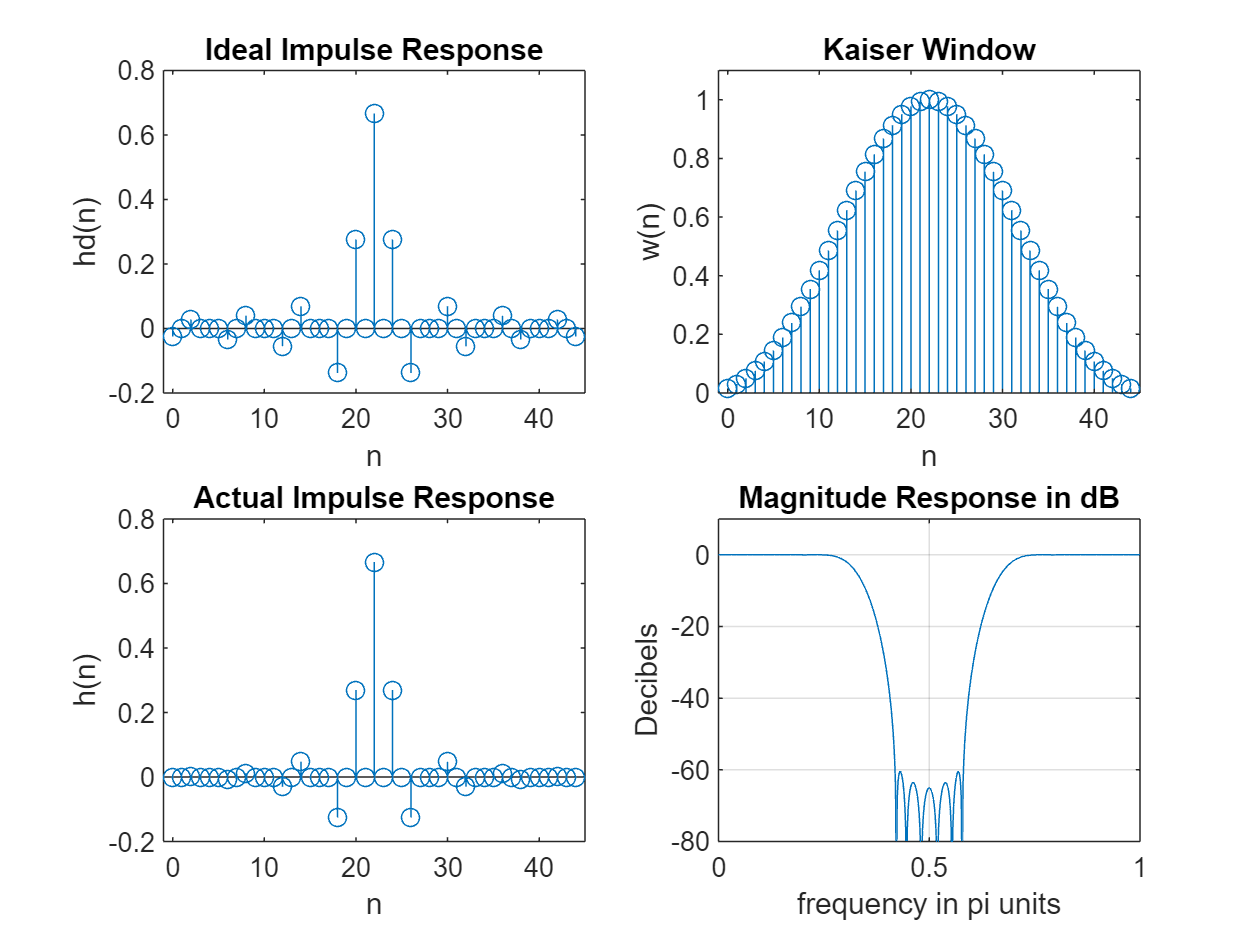

w_kai = (kaiser(M,beta))'; wc1 = pi/3; wc2 = 2*pi/3;
hd = ideal_lp(wc1,M) + ideal_lp(pi,M) - ideal_lp(wc2,M);
h = hd .* w_kai;
[db,mag,pha,grd,w] = freqz_m(h,[1]);
% Plots
figure;
subplot(2,2,1); stem(n,hd);
title('Ideal Impulse Response')
axis([-1 M -0.2 0.8]); xlabel('n'); ylabel('hd(n)')
subplot(2,2,2); stem(n,w_kai);title('Kaiser Window')
axis([-1 M 0 1.1]); xlabel('n'); ylabel('w(n)')
subplot(2,2,3); stem(n,h);title('Actual Impulse Response')
axis([-1 M -0.2 0.8]); xlabel('n'); ylabel('h(n)')
subplot(2,2,4);plot(w/pi,db); axis([0 1 -80 10]);
title('Magnitude Response in dB');grid;
xlabel('frequency in pi units'); ylabel('Decibels');

delta_w = 2*pi/1000;
wcl = 0.422*pi;
wcu = 0.575*pi;
As = -round(max(db(floor(wcl/delta_w+1):1:ceil(wcu/delta_w+1))))

As = 61